mic_calib = 0.8969

mic_calib = 0.8969

piezo_calib = 0.1596

piezo_calib = 0.1596

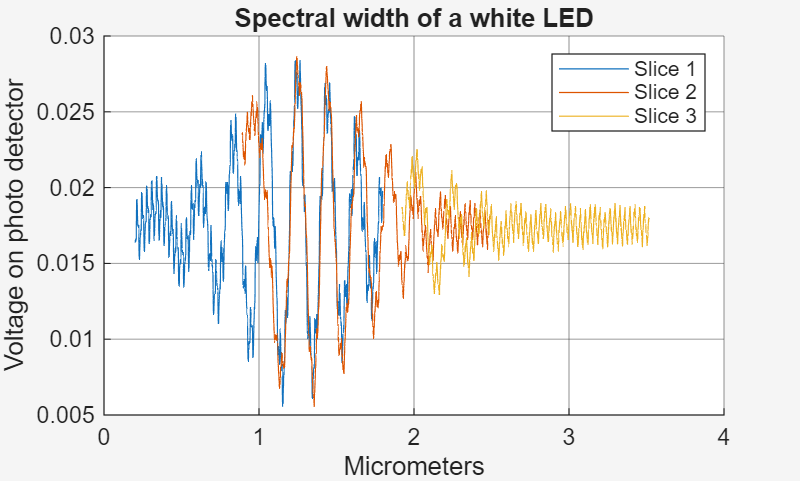


slice = readtable("Task9_16.txt");
time1 = slice.Var4;
detector1 = slice.Var5;
position1 = slice.Var10 * piezo_calib + 1;
isRising = diff(position1) > 0;
position1 = position1(isRising, 1);
detector1 = detector1(isRising, 1);
time1 = time1(isRising, 1);

slice = readtable("Task9_17.txt");
time2 = slice.Var4;
detector2 = slice.Var5;
position2 = slice.Var10 * piezo_calib + 1.69;
isRising = diff(position2) > 0;
position2 = position2(isRising, 1);
detector2 = detector2(isRising, 1);
time2 = time2(isRising, 1);

slice = readtable("Task9_18.txt");
time3 = slice.Var4;
detector3 = slice.Var5;
position3 = slice.Var10 * piezo_calib + 2.72;
isRising = diff(position3) > 0;
position3 = position3(isRising, 1);
detector3 = detector3(isRising, 1);
time3 = time3(isRising, 1);



figure;
hold on;
plot(position1, detector1)
plot(position2, detector2)
plot(position3, detector3)
title("Spectral width of a white LED")
xlabel("Micrometers")
ylabel("Voltage on photo detector")
legend("Slice 1", "Slice 2", "Slice 3")
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'white_led_spectral_width.png', 'Resolution', 300)